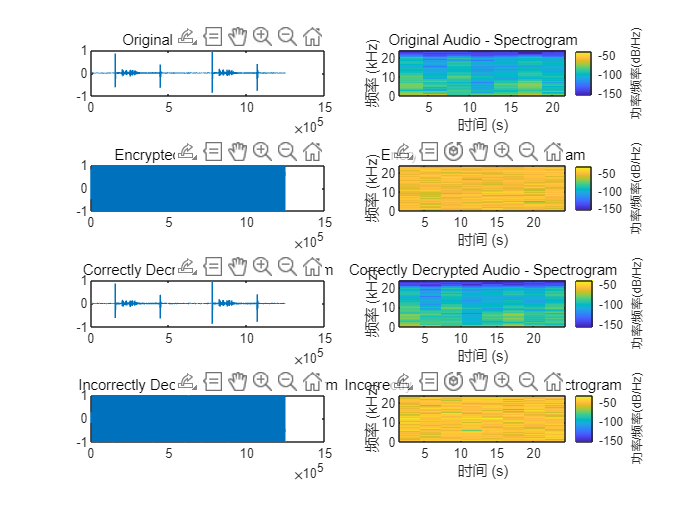

% 读取原始音频文件
original_file = 'tii.wav';
[original_audio, original_fs] = audioread(original_file);
original_audio = squeeze(original_audio);

% 读取加密后的音频文件
encrypted_file = 'encrypted_audio.wav';
[encrypted_audio, encrypted_fs] = audioread(encrypted_file);
encrypted_audio = squeeze(encrypted_audio);

% 读取解密后的音频文件
decrypted_file = 'decrypted_audio.wav';
[decrypted_audio, decrypted_fs] = audioread(decrypted_file);
decrypted_audio = squeeze(decrypted_audio);

% 读取错误解密后的音频文件
incorrect_decrypted_file = 'wdecrypted_audio.wav';
[incorrect_decrypted_audio, incorrect_decrypted_fs] = audioread(incorrect_decrypted_file);
incorrect_decrypted_audio = squeeze(incorrect_decrypted_audio);

original_audio = original_audio(:);  % 将原始音频数据转换为列向量
encrypted_audio = encrypted_audio(:);  % 将加密后音频数据转换为列向量
decrypted_audio = decrypted_audio(:);  % 将解密后音频数据转换为列向量
incorrect_decrypted_audio = incorrect_decrypted_audio(:);  % 将错误解密后音频数据转换为列向量

% 绘制波形和频谱比较图
figure;

% 原始音频
subplot(4, 2, 1);
plot(original_audio);
title('Original Audio - Waveform');

subplot(4, 2, 2);
spectrogram(original_audio, [], [], [], original_fs, 'yaxis');
title('Original Audio - Spectrogram');

% 加密后音频
subplot(4, 2, 3);
plot(encrypted_audio);
title('Encrypted Audio - Waveform');

subplot(4, 2, 4);
spectrogram(encrypted_audio, [], [], [], encrypted_fs, 'yaxis');
title('Encrypted Audio - Spectrogram');

% 解密后音频
subplot(4, 2, 5);
plot(decrypted_audio);
title('Correctly Decrypted Audio - Waveform');

subplot(4, 2, 6);
spectrogram(decrypted_audio, [], [], [], decrypted_fs, 'yaxis');
title('Correctly Decrypted Audio - Spectrogram');

% 错误解密后音频
subplot(4, 2, 7);
plot(incorrect_decrypted_audio);
title('Incorrectly Decrypted Audio - Waveform');

subplot(4, 2, 8);
spectrogram(incorrect_decrypted_audio, [], [], [], incorrect_decrypted_fs, 'yaxis');
title('Incorrectly Decrypted Audio - Spectrogram');